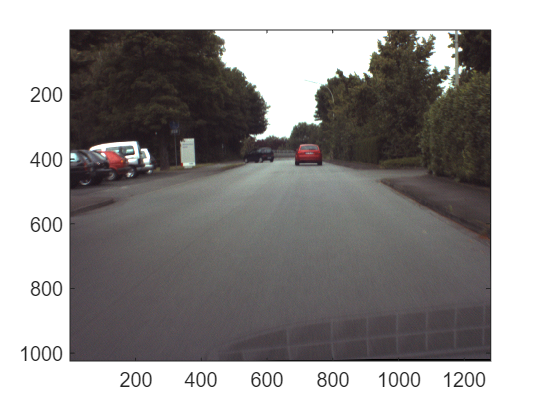

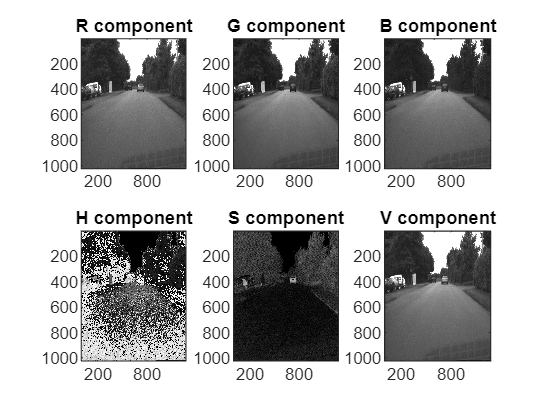

im1=imread("ur_c_s_03a_01_L_0381.png");
im2=imread("ur_c_s_03a_01_L_0380.png");
im3=imread("ur_c_s_03a_01_L_0379.png");
im4=imread("ur_c_s_03a_01_L_0378.png");
im5=imread("ur_c_s_03a_01_L_0377.png");
im6=imread("ur_c_s_03a_01_L_0376.png");

im1hsv=splitChannel(im1);

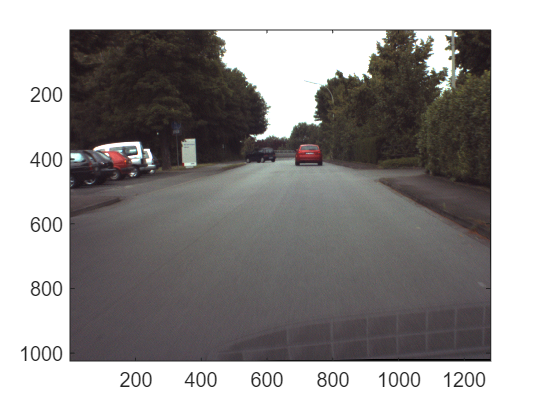

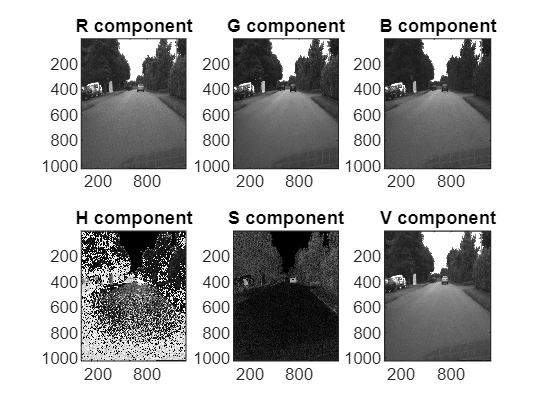

im2hsv=splitChannel(im2);

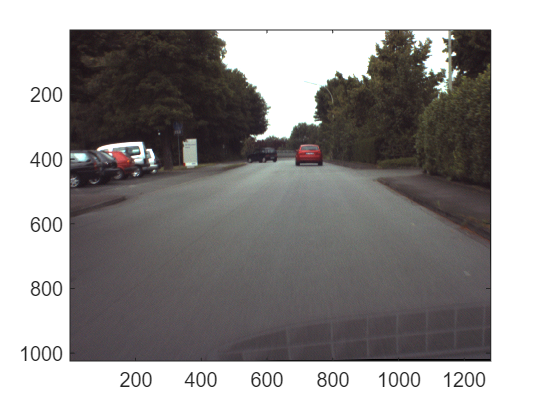

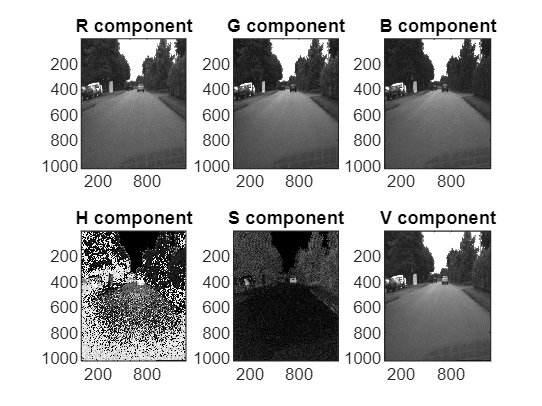

im3hsv=splitChannel(im3);

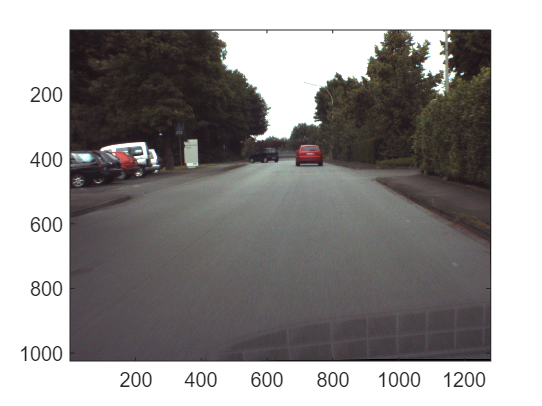

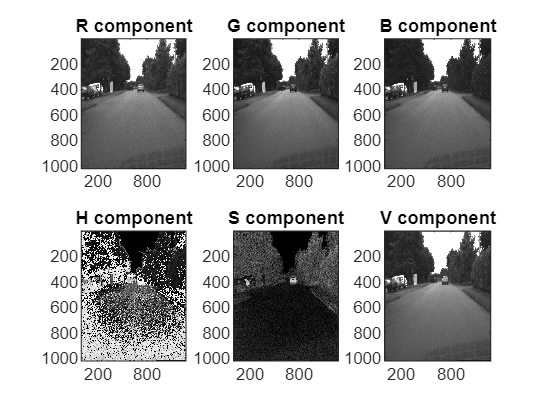

im4hsv=splitChannel(im4);

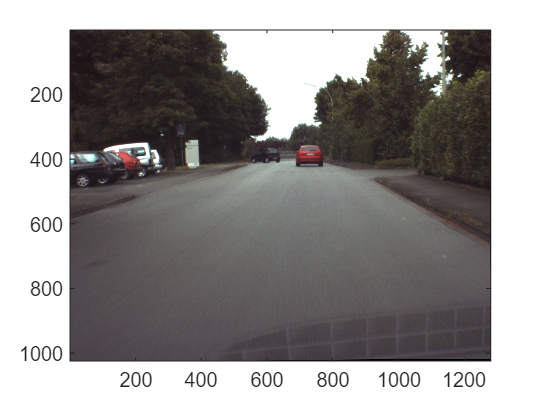

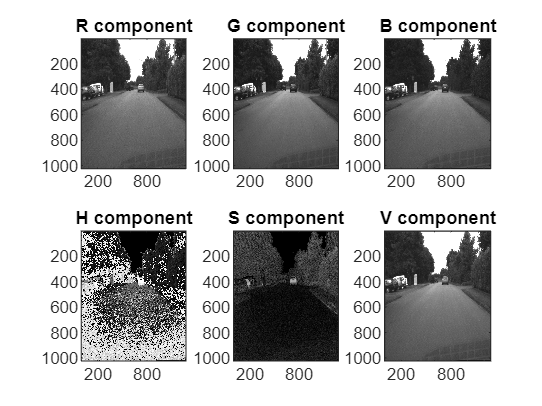

im5hsv=splitChannel(im5);

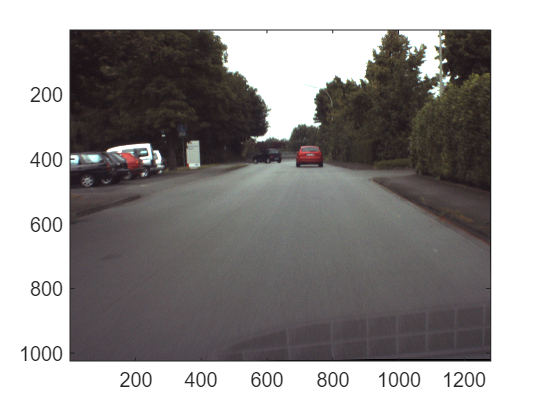

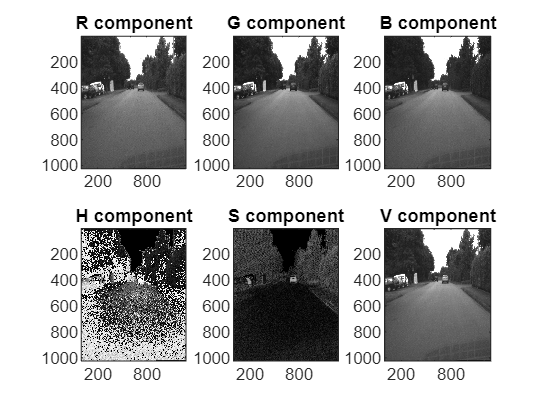

im6hsv=splitChannel(im6);

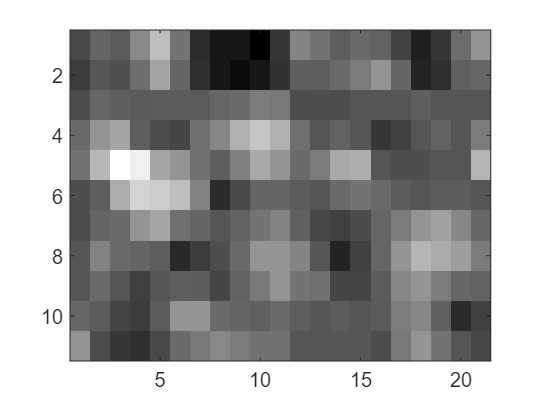



img6CarLeft=rgb2hsv(im6);
img6CarLeftHsv=img6CarLeft(390:400,575:595,1); %use this

figure,imagesc(img6CarLeftHsv),colormap gray

m = 1203

i = 9534

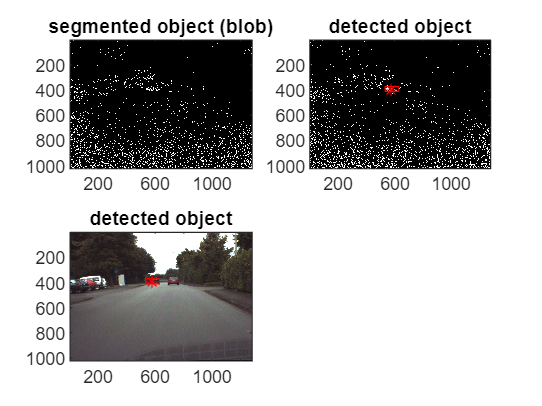


meanvalImg=mean2(img6CarLeftHsv);
standardDeviationImg=std2(img6CarLeftHsv);

%simpleSegmentation(img6CarLeft,meanvalImg,standardDeviationImg);

%figure,seg1=simpleSegmentation(im1hsv,meanvalImg,standardDeviationImg);
figure,seg2=simpleSegmentation(im2hsv,meanvalImg,standardDeviationImg);

m = 2773

i = 19533

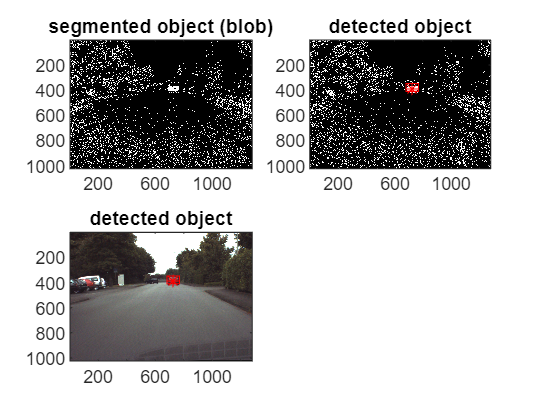

% figure,seg3=simpleSegmentation(im3hsv,meanvalImg,standardDeviationImg);
% figure,seg4=simpleSegmentation(im4hsv,meanvalImg,standardDeviationImg);
% figure,seg5=simpleSegmentation(im5hsv,meanvalImg,standardDeviationImg);
% figure,seg6=simpleSegmentation(im6hsv,meanvalImg,standardDeviationImg);

m=0.97;
s=0.03;
figure,seg1=simpleSegmentation(im1hsv,m,s);

function img_hsv=splitChannel(img)
img_hsv=rgb2hsv(img);
figure,image(img)
figure,subplot(236)
subplot(231),imagesc(img(:,:,1)),colormap gray,title('R component')%as intensity
subplot(232),imagesc(img(:,:,2)),colormap gray,title('G component')%as intensity
subplot(233),imagesc(img(:,:,3)),colormap gray,title('B component')%as intensity
subplot(234),imagesc(img_hsv(:,:,1)),colormap gray,title('H component')%as intensity
subplot(235),imagesc(img_hsv(:,:,2)),colormap gray,title('S component')%as intensity
subplot(236),imagesc(img_hsv(:,:,3)),colormap gray,title('V component')%as intensity
end

function seg=simpleSegmentation(img_hsv,m,s)
[rr,cc,pp]=size(img_hsv);
seg=zeros(rr,cc);
mask=img_hsv(:,:,1)>m-s & img_hsv(:,:,1)<m+s; %threshold on the hue componet
seg=seg+mask;
figure()
subplot(2,2,1),imagesc(seg),colormap gray, title('segmented object (blob)') %binary image (segmented image, i.e. detection of a given color)



prop=regionprops(mask, 'Area','Centroid','BoundingBox');
[m,i]=max([prop.Area])
xc=floor(prop(i).Centroid(1));
yc=floor(prop(i).Centroid(2));
ul_corner_width=prop(i).BoundingBox;

subplot(2,2,2),imagesc(seg),colormap gray,title('detected object')
hold on
plot(xc,yc,'*r')
rectangle('Position',ul_corner_width,'EdgeColor',[1,0,0])

subplot(2,2,3),imagesc(hsv2rgb(img_hsv)),colormap gray,title('detected object')
hold on
plot(xc,yc,'*r')
rectangle('Position',ul_corner_width,'EdgeColor',[1,0,0])




end